SFD and BMD v2

close all;
clear;

L = 1200;  % Length of bridge
n = L;  % Discretize into 1 mm seg.
P = 400;  % Total weight of train [N]
n_train = L-960;  % Number of train locations

lhs_dist = linspace(0, L, n+1);

% Offset by 1 because MALDLAB indexes with 1
% Offset by 1 more to shift cumsum one left
x_shear_start_locations = [52, 228, 392, 568, 732, 908] + 2;
x_train_loads = [-P/6, -P/6, -P/6, -P/6, -P/6, -P/6];
start_shear_all = (720-(0:1:n_train)')/3;  % Column vector of all possible starting shears
all_train_locations = zeros(n_train+1, n+1);

for i = 0:n_train
    all_train_locations(i+1, x_shear_start_locations+i) = x_train_loads;
end

% Each row is an SFD for each train location
all_shear = zeros(n_train+1, n+1);
all_shear(:,1) = start_shear_all;
all_shear = all_shear + all_train_locations;
all_shear = cumsum(all_shear, 2);

% Each row is a BMD for each train location
all_moment = cumsum(all_shear, 2);
all_moment = all_moment - start_shear_all;

x = 76  % Location of the train (not needed anymore)

x = 76


moment_envelope = max(all_moment)

moment_envelope = 1.0e+04 *

         0    0.0240    0.0480    0.0720    0.0960    0.1200    0.1440    0.1680    0.1920    0.2160    0.2400    0.2640    0.2880    0.3120    0.3360    0.3600    0.3840    0.4080    0.4320    0.4560    0.4800    0.5040    0.5280    0.5520    0.5760    0.6000    0.6240    0.6480    0.6720    0.6960    0.7200    0.7440    0.7680    0.7920    0.8160    0.8400    0.8640    0.8880    0.9120    0.9360    0.9600    0.9840    1.0080    1.0320    1.0560    1.0800    1.1040    1.1280    1.1520    1.1760


shear_envelope = max(abs(all_shear))

shear_envelope =    240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240


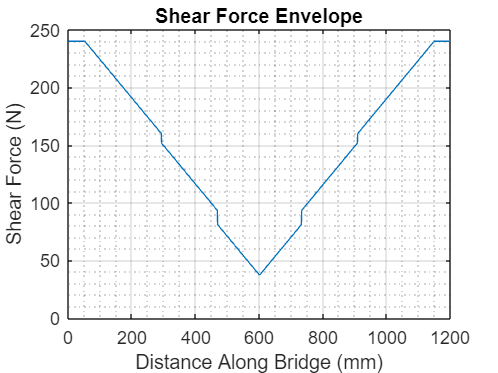


figure
plot(lhs_dist, max(abs(all_shear)))
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Shear Force Envelope")

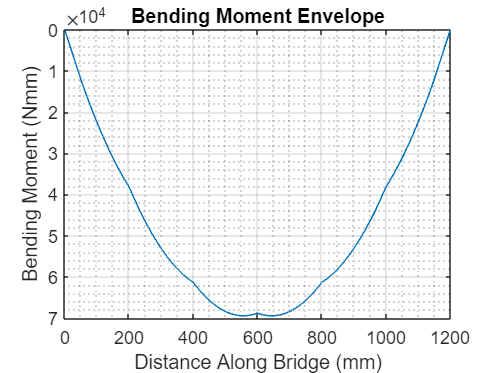


figure
plot(lhs_dist, max(all_moment))
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Envelope")


x_shear = all_shear(x+1,:);
x_moment = all_moment(x+1,:);

%{
figure
plot(lhs_dist, x_shear)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Shear Force Diagram")

figure
plot(lhs_dist, x_moment)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Diagram")
%}

Bridge Geometry

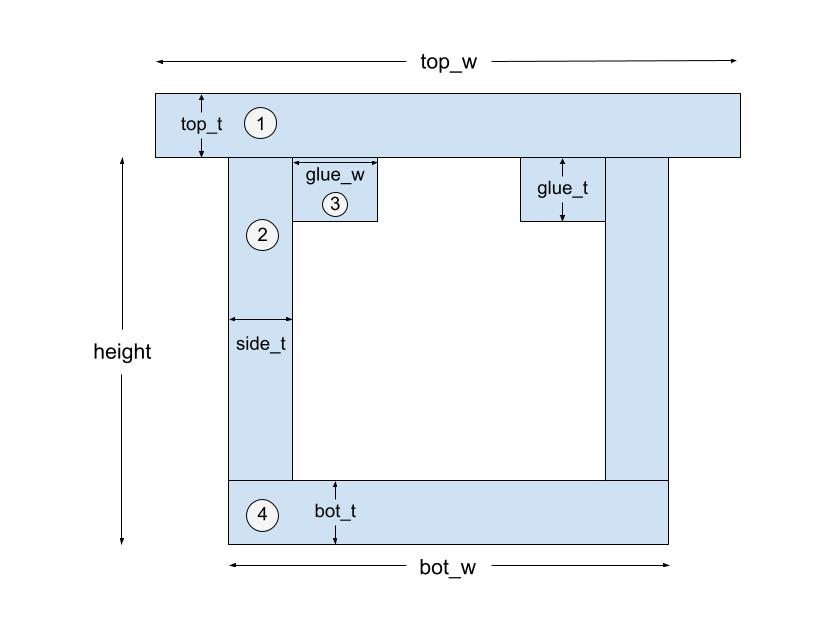

% Define params
top_w = 140;
bot_w = 75;  % modified
height = 100; % defined from lowest point without including thickness of the top area
top_t = 1.27*2;  % modified
bot_t = 1.27;
side_t = 1.27;
glue_w = 5; % not including thickness of side
glue_t = 1.27;

Cross-sectional Properties

% Calculate y bar, I, Q_glue, Q_cent
area_1 = top_t * top_w;
area_2 = (height - bot_t)*side_t;
area_3 = glue_w * glue_t;
area_4 = bot_t*bot_w;

y1 = height+top_t/2;
y2 = (height+bot_t)/2;
y3 = height - glue_t/2;
y4 = bot_t/2;

I1 = top_w*(top_t^3)/12;
I2 = side_t*((height-bot_t)^3)/12;
I3 = glue_w*(glue_t^3)/12;
I4 = bot_w*(bot_t^3)/12;

tot_area = area_1 + 2*area_2 + 2*area_3 + area_4;

y_bar = (area_1*y1 + 2*area_2*y2 + 2*area_3*y3 + area_4*y4)/tot_area

y_bar = 70.0410


d1 = y1-y_bar;
d2 = y2-y_bar;
d3 = y3-y_bar;
d4 = y4-y_bar;

sec1 = area_1*(d1^2) + I1;
sec2 = 2*(area_2*(d2^2) + I2);
sec3 = 2*(area_3*(d3^2) + I3);
sec4 = area_4*(d4^2) + I4;

I = sec1+sec2+sec3+sec4

I = 1.1149e+06


Q_cent = (bot_w - 2*side_t)*bot_t*(y_bar - bot_t/2) + 2*y_bar*side_t*y_bar/2

Q_cent = 1.2617e+04

Q_glue = area_1 * (height-y_bar + 1.27/2)

Q_glue = 1.0879e+04

Stresses

% sigma top + bottom, sigma buck tau max tau glue tau buck
[moment_max,x_moment_max] = max(x_moment);
[shear_max,x_shear_max] = max(x_shear)

shear_max = 214.6667

x_shear_max = 1

sigma_top_max = -moment_max *(height+top_t-y_bar)/I;
sigma_bot_max = moment_max *y_bar/I;
shear_max = max(x_shear);
T_cent_max = shear_max * Q_cent/(I*(2*side_t));
T_glue_max = shear_max *Q_glue/(I*(2*glue_w));

sigma_top = -moment_envelope .* (height+top_t-y_bar)/I

sigma_top =          0   -0.0070   -0.0140   -0.0210   -0.0280   -0.0350   -0.0420   -0.0490   -0.0560   -0.0630   -0.0700   -0.0770   -0.0840   -0.0909   -0.0979   -0.1049   -0.1119   -0.1189   -0.1259   -0.1329   -0.1399   -0.1469   -0.1539   -0.1609   -0.1679   -0.1749   -0.1819   -0.1889   -0.1959   -0.2029   -0.2099   -0.2169   -0.2239   -0.2309   -0.2379   -0.2449   -0.2519   -0.2588   -0.2658   -0.2728   -0.2798   -0.2868   -0.2938   -0.3008   -0.3078   -0.3148   -0.3218   -0.3288   -0.3358   -0.3428


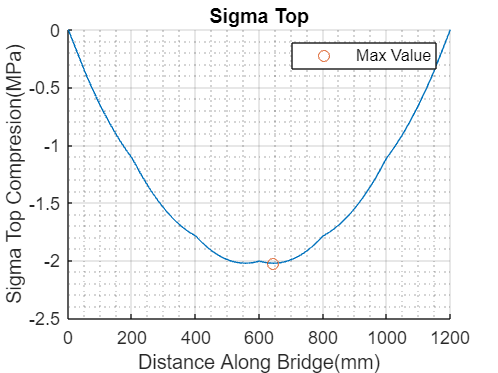

sigma_bot = moment_envelope .*y_bar/I;

T_cent = shear_envelope .* Q_cent/(I*(2*side_t));
T_glue = shear_envelope .* Q_glue/(I*(2*glue_w));


%graph for sigma top
figure
hold on
plot(0:1200,sigma_top)
plot(x_moment_max,sigma_top(x_moment_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Sigma Top Compresion(MPa)")
title("Sigma Top")
grid on
grid minor
legend("","Max Value")

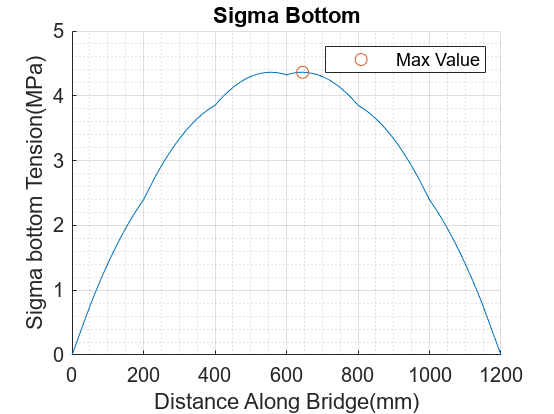

figure

%graph for sigma bottom
hold on
plot(0:1200,sigma_bot)
plot(x_moment_max,sigma_bot(x_moment_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Sigma bottom Tension(MPa)")
grid on
grid minor
legend("","Max Value")
title("Sigma Bottom")

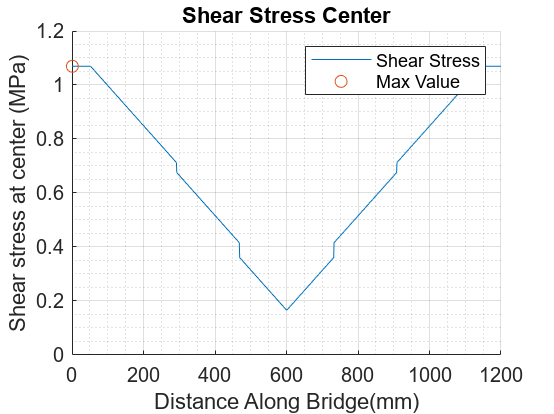

figure
%graph for shear stress at center
hold on
plot(0:1200,T_cent)
plot(x_shear_max,T_cent(x_shear_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear stress at center (MPa)")
grid on
grid minor
legend("Shear Stress","Max Value")
title("Shear Stress Center")

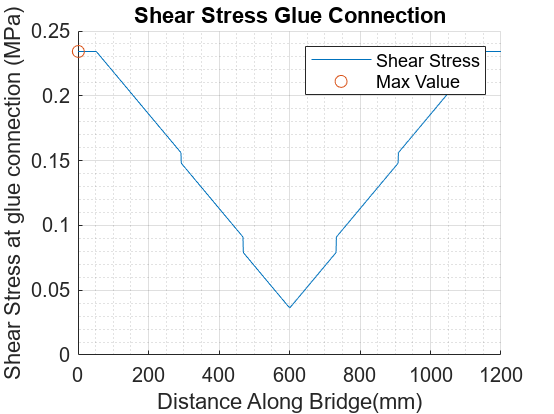

figure

%graph for shear stress at glue connection
hold on
plot(0:1200,T_glue)
plot(x_shear_max,T_glue(x_shear_max),"o")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Stress at glue connection (MPa)")
grid on
grid minor
legend("Shear Stress","Max Value")
title("Shear Stress Glue Connection")

figure


% Amin

Thin Plate

% Kevin
E = 4000

E = 4000

mu = 0.2

mu = 0.2000


% Case 1.1: buckling of the top plate
t11 = top_t

t11 = 2.5400

b11 = bot_w - side_t

b11 = 73.7300

stress_top_plate = (4*pi^2*E)/(12*(1-mu^2)) * (t11/b11)^2

stress_top_plate = 16.2685


%{
Case 1.2: buckling of the bottom plate
t12 = top_t
b12 = bot_w - side_t
stress_bottom_plate = (4*pi^2*E)/(12*(1-mu^2)) * (t12/b12)^2
%}

% Case 2.1: buckling of the side flanges
t_flange = top_t

t_flange = 2.5400

b_out = (top_w-bot_w)/2 + side_t/2

b_out = 33.1350

stress_side_flange = (0.425*pi^2*E)/(12*(1-mu^2)) * (t_flange/b_out)^2

stress_side_flange = 8.5583


% Case 3.1: buckling due to varying shears
t_web31 = side_t

t_web31 = 1.2700

y_top = height - y_bar

y_top = 29.9590

stress_varying_shear = (6*pi^2*E)/(12*(1-mu^2)) * (t_web31/y_top)^2

stress_varying_shear = 36.9497


% Case 4.1: shear buckling
t_web41 = side_t

t_web41 = 1.2700

h_web41 = height - glue_t/2 - bot_t/2

h_web41 = 98.7300

a = 400

a = 400

stress_shear_buckle = (5*pi^2*E)/(12*(1-mu^2)) * ((t_web41/h_web41)^2 + (t_web41/a)^2)

stress_shear_buckle = 3.0079

Factor of Safety

sigma_tens = 30

sigma_tens = 30

sigma_comp = 6

sigma_comp = 6

shear_strength = 4

shear_strength = 4

shear_strength_glue = 2

shear_strength_glue = 2



FOS_tension = sigma_tens./sigma_bot;
FOS_comp = -sigma_comp./sigma_top;
FOS_flexbuck1 = -stress_top_plate ./sigma_top;
FOS_flexbuck2 = -stress_side_flange ./ sigma_top;
FOS_flexbuck3 = -stress_varying_shear ./ sigma_top;

FOS_shear = shear_strength ./ T_cent;
FOS_shear_glue = shear_strength_glue ./T_glue;
FOS_shear_buck = stress_shear_buckle ./ T_cent;


Shear Force Capacities + Bending Moment Capacities

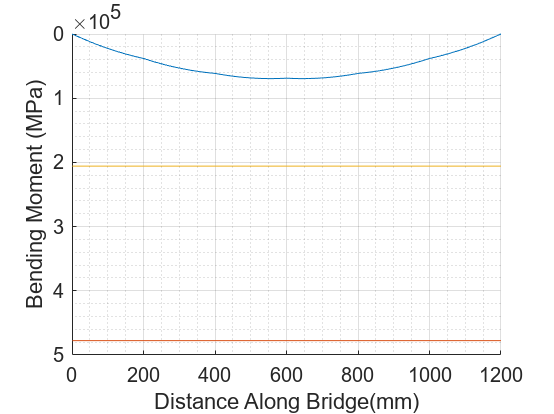

M_fail_tens = FOS_tension .* moment_envelope;
M_fail_comp = FOS_comp .* moment_envelope;
M_fail_buck1 = FOS_flexbuck1 .*moment_envelope;
M_fail_buck2 = FOS_flexbuck2 .* moment_envelope;
M_fail_buck3 = FOS_flexbuck3 .* moment_envelope;

M_fail_shear = FOS_shear .* shear_envelope;
M_fail_shear_glue = FOS_shear_glue .* shear_envelope;
M_fail_shear_buck = FOS_shear_buck .* shear_envelope;

figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(0:1200, moment_envelope)
plot(0:1200, M_fail_tens)
plot(0:1200, M_fail_comp)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
%legend("Bending Moment Diagram", "Matboard Tension Failure", "Matboard Compression Failure")
hold off;

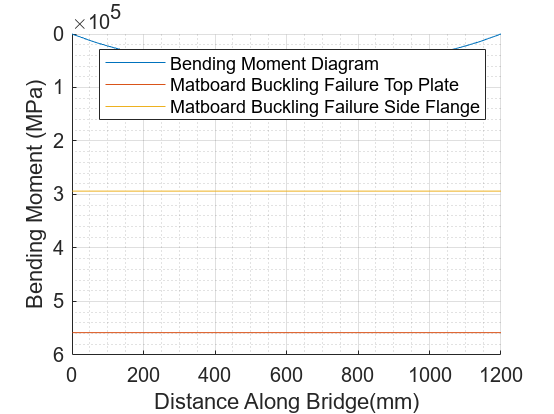


figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(0:1200, moment_envelope)
plot(0:1200, M_fail_buck1)
plot(0:1200, M_fail_buck2)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Buckling Failure Top Plate", "Matboard Buckling Failure Side Flange")
hold off;

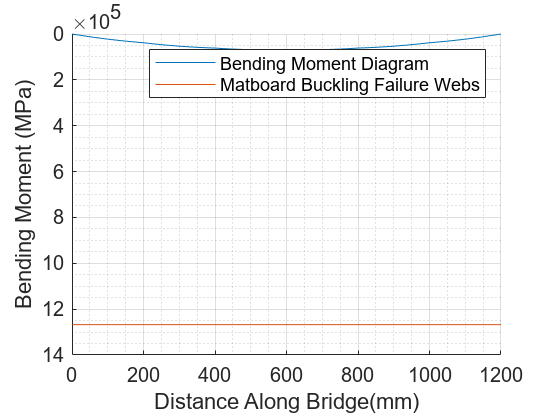


figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(0:1200, moment_envelope)
plot(0:1200, M_fail_buck3)
xlabel("Distance Along Bridge(mm)")
ylabel("Bending Moment (MPa)")
grid on
grid minor
legend("Bending Moment Diagram", "Matboard Buckling Failure Webs")
hold off;

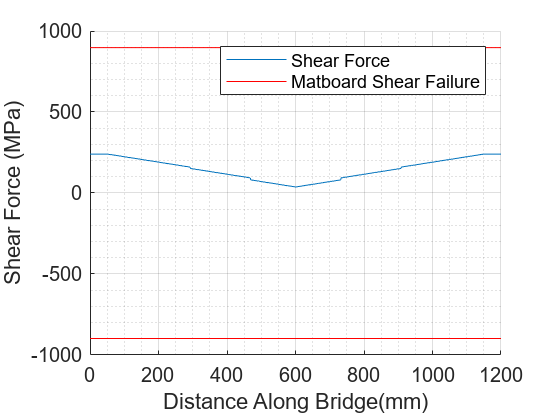


figure
hold on
plot(0:1200, shear_envelope)
plot(0:1200, M_fail_shear,"r")
plot(0:1200, -M_fail_shear,"r")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
legend("Shear Force","Matboard Shear Failure")
hold off

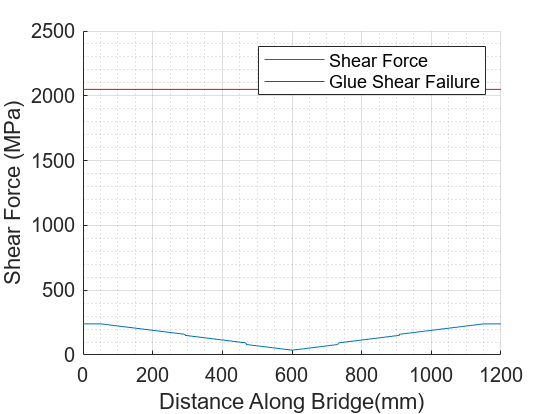




figure 
hold on 
plot(0:1200, shear_envelope)
plot(0:1200, M_fail_shear_glue,"r")
legend("Shear Force","Glue Shear Failure")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
hold off

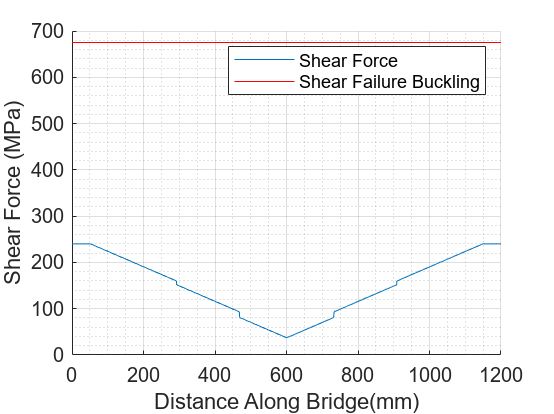


figure 
hold on 
plot(0:1200, shear_envelope)
plot(0:1200, M_fail_shear_buck,"r")
legend("Shear Force","Shear Failure Buckling")
xlabel("Distance Along Bridge(mm)")
ylabel("Shear Force (MPa)")
grid on
grid minor
hold off

min(FOS_tension)

ans = 6.8765

min(FOS_comp)

ans = 2.9640

min(FOS_flexbuck1)

ans = 8.0366

min(FOS_flexbuck2)

ans = 4.2278

min(FOS_flexbuck3)

ans = 18.2531

min(FOS_shear)

ans = 3.7407

min(FOS_shear_glue)

ans = 8.5400

min(FOS_shear_buck)

ans = 2.8130

SA = 1260*(bot_w+top_w+2*(height-bot_t)+2*glue_t)

SA = 5.2290e+05

Surface_area_percent = (1260*(bot_w+top_w+2*(height-bot_t)+2*glue_t))/800000;
Surface_area_percent_left = 1 - Surface_area_percent

Surface_area_percent_left = 0.3464